# Assignment 3

### Consider the two dimensional binary arrays in files person01.mat to person20.mat.   Each  row  of  such  an  array  person[i].m  is  a  binary feature vector of 30 elements that is extracted from an iris image of a person that we call here person[i] (i= 1, . . . ,20).  Hence, each row is a 30-dimensional binary iris code of that person.  There are 20 such iris codes of each person in the corresponding file person[i]; each row of the array is one such binary iris code.

% To load files person[i].mat with i = 1..20
for col = 1:20
    % Generate the file name person[i].mat, [i] is a two-digit number
    file = strcat("person" + num2str(col, '%02d') + ".mat");
    % Load each file and save it in an array
    person(col) = load(file);
end

#### 1.  Take a closer look at the rows of one such array and notice that two row scan differ in only a few positions (bits).  Compare now two rows that come from two different files person[i] and person[j].  Notice that two such iris codes differ in about 15 positions.

% Take a random person
i = randi(20);
% Take the number of rows in the iriscode
nrows = numel(person(i).iriscode(:,1));
% Take the number of columns
ncols = numel(person(i).iriscode(1,:));
% Initialize a matrix where all the differences between different rows will
% be stored
diffRows = zeros(20);

% Loop from each row to the end, so we compare two different rows only once
for row1 = 1:nrows-1
    for row2 = row1+1:nrows
        % Calculate the differences between both rows
        diff = 0;
        for col = 1:ncols
            if person(i).iriscode(row1,col) ~= person(i).iriscode(row2,col)
                diff = diff + 1;
            end
        end
        
        diffRows(row1, row2) = diff;
        diffRows(row2, row1) = diff;
    end
end

diffRows

diffRows =      0     3     3     1     0     0     1     3     2     2     2     1     1     2     0     3     2     0     3     2
     3     0     6     4     3     3     4     6     3     5     5     4     4     5     3     6     3     3     6     5
     3     6     0     4     3     3     4     6     5     5     5     4     4     5     3     6     3     3     4     5
     1     4     4     0     1     1     2     4     3     3     3     2     2     3     1     4     3     1     4     3
     0     3     3     1     0     0     1     3     2     2     2     1     1     2     0     3     2     0     3     2
     0     3     3     1     0     0     1     3     2     2     2     1     1     2     0     3     2     0     3     2
     1     4     4     2     1     1     0     4     3     3     1     2     2     3     1     4     3     1     4     1
     3     6     6     4     3     3     4     0     5     3     5     4     2     5     3     6     5     3     4     5
     2     3     5   


% Take two different people
i = 3;
j = 6;
diff = 0;
% Calculate the differences (We chose the first row of each person's iriscode)
for col = 1:ncols
    if person(i).iriscode(1,col) ~= person(j).iriscode(1,col)
        diff = diff + 1;
    end
end

fprintf("Person %i and person %i differ in %i positions", i, j, diff)

Person 3 and person 6 differ in 14 positions

#### 2.  The  Hamming  distance  (HD)  of  two  binary  iris  codes  is  the  number  of positions  (bits)  in  which  the  two  codes  (binary  feature  vectors)  differ. Compute two sets S and D of 1000 HD values each as follows:

(a)  For set S: Choose randomly one of the files person[i].mat, i= 1, . . . ,20. Choose randomly two rows in that file.  Compute the HD of these two rows.  Normalize the HD by dividing it by 30.  Repeat this process 1000  times  to  obtain  1000  HD  values.(hint:   create  a  string  array  containing  strings  ’person01.mat’,  ’person02.mat’  etc,  using  the function char, to be able to load a random file).

% Initialize an array S with 1000 values
S = zeros(1, 1000);
% Compute 1000 HD values using two random rows of a random person
for n = 1:1000
    pers = randi([1, 20]);
    row1 = randi([1, 20]);
    row2 = randi([1, 20]);
    S(n) = hd(person(pers).iriscode(row1, :), person(pers).iriscode(row2, :))/30;
end
S

S =          0    0.0667    0.0333    0.0667    0.1000    0.1000    0.1000    0.0667    0.0667    0.1000    0.1000         0    0.0667    0.0667    0.1000    0.1000    0.1000    0.0333    0.1000    0.0667    0.0333    0.0667         0    0.0667    0.0333    0.0333    0.0667    0.0667    0.0333    0.0333    0.1333    0.0667    0.1333    0.0667    0.0333    0.0667    0.1000    0.1000    0.0667    0.1333    0.1333    0.0667    0.0667         0    0.0667    0.0333    0.1000    0.2000    0.0333    0.1000


(b)  For set D: Choose randomly two different files person[i].mat and person[j].mat, i= 1, . . . ,20; j= 1, . . . ,20; i ~= j.  Choose randomly one row from each of these two files.  Compute the HD of these two rows. Normalize  the  HD  by  dividing  it  by  30. Repeat  this  process  1000 times to obtain 1000 HD values.

% Initialize an array D with 1000 values
D = zeros(1, 1000);
% Compute 1000 HD values using two random rows of two random different
% people
for n = 1:1000
    pers1 = randi([1, 20]);
    pers2 = randi([1, 20]);
    while pers1 == pers2
        pers2 = randi([1, 20]);
    end
    row1 = randi([1, 20]);
    row2 = randi([1, 20]);
    D(n) = hd(person(pers1).iriscode(row1, :), person(pers2).iriscode(row2,:))/30;
end
D

D =     0.6667    0.3667    0.4333    0.4000    0.3333    0.4667    0.4000    0.5000    0.4000    0.5000    0.5667    0.4333    0.5667    0.4667    0.5333    0.5000    0.5667    0.4333    0.4667    0.5667    0.5000    0.4333    0.3667    0.5667    0.4667    0.5333    0.6000    0.4667    0.4000    0.3333    0.4667    0.5667    0.5000    0.4667    0.3667    0.4333    0.4000    0.4667    0.5000    0.5667    0.6000    0.3667    0.5667    0.6333    0.6667    0.4333    0.4333    0.4667    0.6000    0.4333


#### 3.  Plot the histograms of S and D in one figure with different colors.  How much do the two histograms overlap?

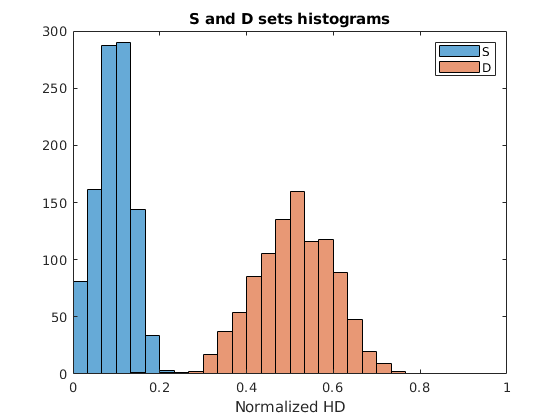

SHist = histogram(S, 30, 'BinLimits',[0, 1]);
hold on
DHist = histogram(D, 30, 'BinLimits',[0, 1]);
title('S and D sets histograms');
legend('S', 'D');
xlabel('Normalized HD');
xlim([0 1])
hold off

The two hisograms overlap  around the values 0.2 and 0.24.

#### 4.  Compute the means and the variances of the sets S and D. Add to the histograms of the previous question (4.3), plots of two normal distributions (Gaussian functions) with these means and variances.  How well do the normal distributions fit the histograms?

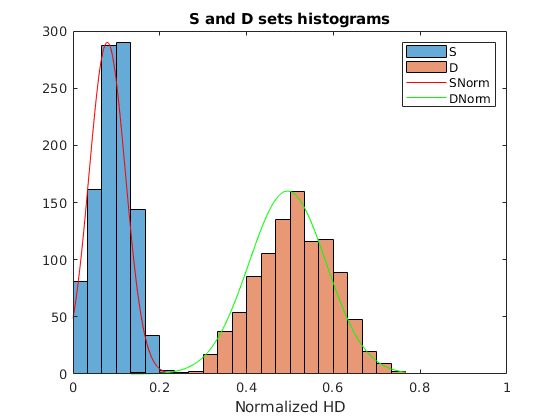

% Firstly, compute the mean and variance
SMean = mean(S);
SVar = var(S);
% Then, find the range of the histogram by finding the first and last
% values non-null values
SFirstVal = find(SHist.Values, 1, 'first');
% The [0, 1] interval is divided in 30 spaces, so the histogram has 31
% edges. That means that the last non-null value's edge has 1 index more
% than the number of the column to which it is edge
SLastVal = find(SHist.Values, 1, 'last') + 1;
% Generate linearly spaced vector between both first and last non-null
% values
SRange = linspace(SHist.BinEdges(SFirstVal), SHist.BinEdges(SLastVal));
% Finally, generate a normal distribution which fits in this range
SNorm = normpdf(SRange, SMean, sqrt(SVar));
% Also, amplify the graph so that it has the same height as the histogram
SNorm = SNorm/max(SNorm)*max(SHist.Values);

% Do the same with the D set
DMean = mean(D);
DVar = var(D);
DFirstVal = find(DHist.Values, 1, 'first');
DLastVal = find(DHist.Values, 1, 'last') + 1;
DRange = linspace(DHist.BinEdges(DFirstVal), DHist.BinEdges(DLastVal));
DNorm = normpdf(DRange, DMean, sqrt(DVar));
DNorm = DNorm/max(DNorm)*max(DHist.Values);

hold on
plot(SRange, SNorm, 'r')
plot(DRange, DNorm, 'g')
legend('S', 'D', 'SNorm', 'DNorm')
hold off

As we can see by looking at the plot, both normal distributions fit the histograms pretty well. This means that both sets follow a normal distribution.

#### 5.  (BONUS) The distribution associated with the set S is the class-conditional probability density function that we measure a certain HD value for two iris  codes  of  the  same  person.   The  distribution  associated  with  the  set D  is  the  class-conditional  probability  density  function  that  we  measure a certain HD value for two iris codes of two different persons.  Estimate the value of the decision criterion for which the false acceptance error is approximately 0.0005.  False acceptance occurs when the iris codes of two different persons are declared to be sufficiently similar so that one can assume that they come from the same person.  For that value of the decision criterion, determine the false rejection rate.  False rejection occurs when two iris codes of the same person have a HD which is above the decision criterion so that they will wrongly be assumed to come from two different persons.  (Note that here the terms acceptance (of an impostor) and rejection (of an authentic person) are related to the alternative hypothesis stating that two iris codes which are compared come form the same person, the zero hypothesis being that they come from two different persons. False  acceptance  and  false  rejection  thus  correspond  to  an  error  type  I and II, respectively, in terms of statistical decision theory and hypothesis testing.)

% Compute both cumulative distribution functions of the S and D sets
DNormCDF = normcdf(DRange, DMean, sqrt(DVar));
SNormCDF = normcdf(SRange, SMean, sqrt(SVar));
% To get the false acceptance error below 0.0005, we iterate the cdf
% function of the D set until we get as close as possible to the value
Ddc = 0;
while Ddc < numel(DNormCDF)-1 && DNormCDF(Ddc+1) < 0.0005
    Ddc = Ddc + 1;
end
% To find the false rejection rate, we must firstly find the index where
% the decision criterion is, so we iterate until we find it
Sdc = 0;
while Sdc < numel(SRange)-1 && SRange(Sdc+1) < DRange(Ddc)
    Sdc = Sdc + 1;
end

fprintf('The decision criterion is set at %.4f, considering HD normalized.', DRange(Ddc));

The decision criterion is set at 0.1973, considering HD normalized.

fprintf('In absolute numbers that is %.4f.', DRange(Ddc)*30)

In absolute numbers that is 5.9192.

fprintf(['Furthermore, the false acceptance rate for this value of the decision ' ...
    'criterion is %.6f, and the false rejection rate is %.6f.'], DNormCDF(Ddc), 1-SNormCDF(Sdc));

Furthermore, the false acceptance rate for this value of the decision criterion is 0.000426, and the false rejection rate is 0.002614.

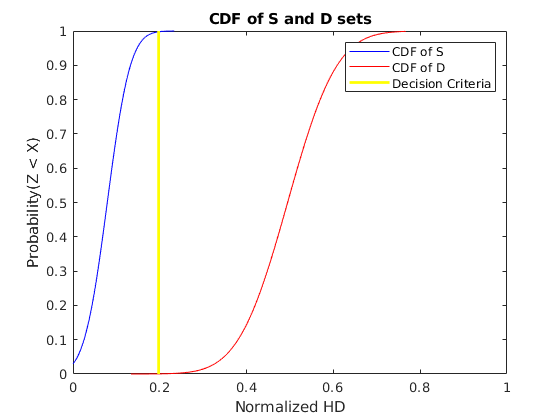


plot(SRange, SNormCDF, 'b')
hold on
plot(DRange, DNormCDF, 'r')
line([DRange(Ddc) DRange(Ddc)], ylim, 'LineWidth', 2, 'Color', 'y')
title('CDF of S and D sets')
xlabel('Normalized HD')
ylabel('Probability(Z < X)')
legend('CDF of S', 'CDF of D', 'Decision Criteria')
xlim([0 1])
hold off

function y = hd(b1, b2)
    y = 0;
    for n = 1:30
        if b1(n) ~= b2(n)
            y = y + 1;
        end
    end
end
